## Issue in [IndexesREFdomain.m](matlab:open('/home/joaquin/Desktop/CURRENT_TASKS/MATLAB_CODES/FE_HROM/DOMAINdecompHROM/MultiHROM/IndexesREFdomain.m'))

% ----------------------------------
% BOUNDARY  ELEMENTS 
% -------------------------------------------
% See AUX_IndexesREFdomain.mlx
% MESH.CNb --- > Boundary elements.  MESH.CNb(ielem,nodeGLOnumbering)
% We want to determine its counterpart with local numbering
CNb_dom = cell(1,size(MESH.CNb,2)) ; 
ia ={} ; C ={} ;
for inodeLOC = 1:size(MESH.CNb,2) % Loop over the columns of MESH.CNb
    [C{inodeLOC},ia{inodeLOC},CNb_dom{inodeLOC}] =     intersect(MESH.CNb(:,inodeLOC),INFO_RVE.NODES_globNUM,'stable') ;   
end
MESHdom.CNb = cell2mat(CNb_dom) ; 

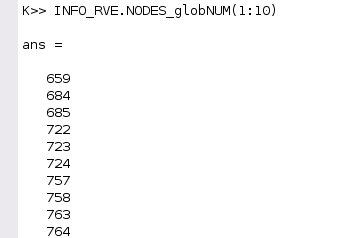

The above is just the numbering of the domain nodes in the original  mesh ---entire mesh, I mean. What do we want?  WE have the connecivity matrix of the all the boundary nodes in MESH.CNb.  How to do that ? By invoking function INTERSECT in Matlab. 

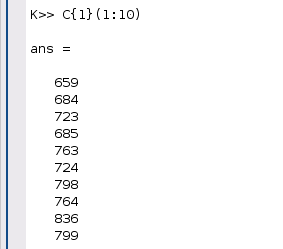 

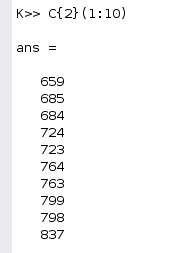

What how C{1} and C{2} identical ?  Ok. Let us do it serially for the time being. 